## Define Lattice

atom = Alkali("Lithium7");
laser = GaussianBeam( ...
    wavelength = 1064e-9,...
    direction = [0;1;0],...
    polarization = [0;0;1],...
    power = 1, ...
    waist = 110e-6 ...
    );
ol = OpticalLattice(atom,laser);
kL = ol.Laser.AngularWavenumber;
Er = ol.RecoilEnergy;
ol.DepthSpec = 8.4598 * Er;
% ol.DepthSpec = 20 * Er;
ol.updateIntensity;
ol.computeAll1D(1e4,7)


## Band Structure 

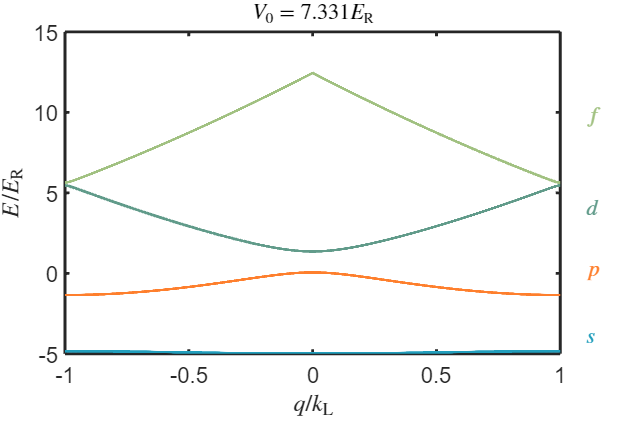

maxBandIdx = 3;
ol.plotBand1D(0:maxBandIdx)

## Transition 

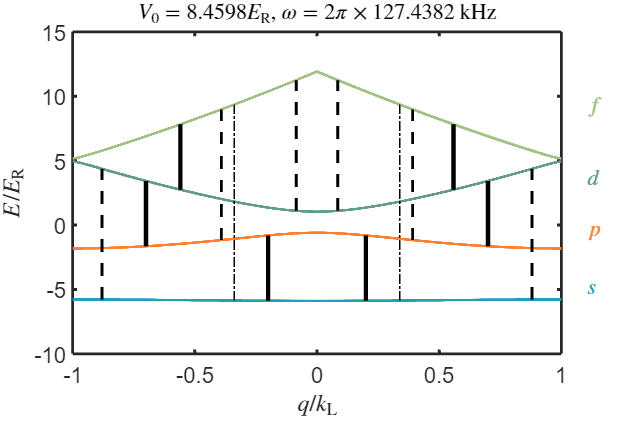

% driveFreq = 77.0931276e3;
driveFreq = 127.4382e3;
% driveFreq = 115e3;
% driveFreq = 143.2231e3;
maxBandIdx = 3;
ol.plotBandTransition1D(driveFreq,0:maxBandIdx)

## Compute Transition Quasi-momentum from Driving Frequency

driveFreq = 215e3;
bandIdx1 = 2;
bandIdx2 = 3;
qRes = ol.computeTransitionQuasiMomentum1D(driveFreq,bandIdx1,bandIdx2);
disp("Transition quasi-momentum from band " + num2str(bandIdx1) + ...
    " to band " + num2str(bandIdx2) + ...
    " at f=" + num2str(driveFreq) + " Hz:" + ...
    newline + ...
    + qRes/kL + " kL")

Transition quasi-momentum from band 2 to band 3 at f=215000 Hz:
0.24418 kL


## Compute Driving Frequency from Quasi-momentum

qRes = 0.5 * kL;
bandIdx1 = 0;
bandIdx2 = 2;
driveFreq = ol.computeTransitionFrequency1D(qRes,bandIdx1,bandIdx2);
disp("Transition frequency from band " + num2str(bandIdx1) + ...
    " to band " + num2str(bandIdx2) + ...
    " at q=" + num2str(qRes/kL) + ":" + ...
    newline + ...
    + driveFreq + " Hz")

Transition frequency from band 0 to band 2 at q=0.5:
196900.617 Hz


## Amplitude Modulation Coupling

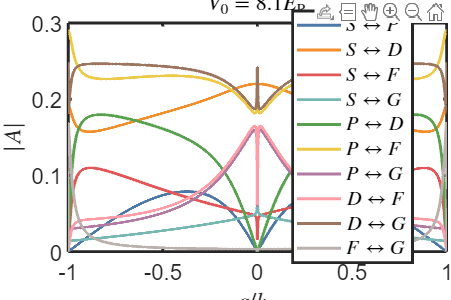

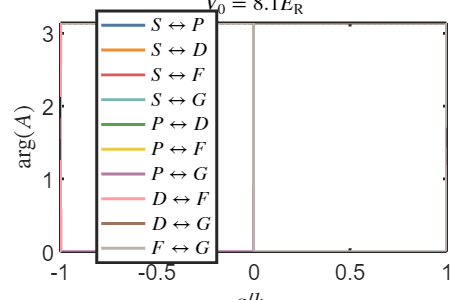

maxBandIdx = 4;
ol.plotAmpModCoupling1D(0:maxBandIdx)

## Berry Connection

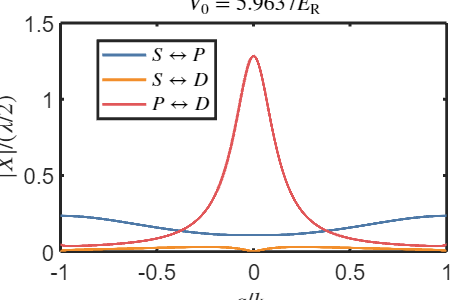

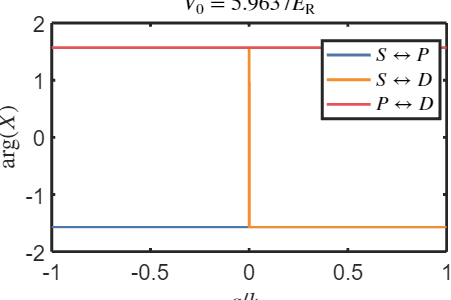

maxBandIdx = 2;
ol.plotBerryConnection1D(0:maxBandIdx)